v0 = [1,1];
v0 = v0./norm(v0,2);

p0 = [1, -1; 3, 1; 1, 3; -1, 1; 1, -1];
p0 = p0';
c = [4;2];
p0 = p0 + ndgrid(c,1:5);

theta = pi/2 - atan2(v0(2),v0(1));
R = rotz(theta);
R = R(1:2,1:2);
p1 = R*p0 - R*ndgrid(c,1:5);
p2 = R*p0 - ndgrid(c,1:5);
p3 = R*p0;

figure;
% line([0,v0(1)],[0,v0(2)],'b'); hold on;
plot(p0(1,:),p0(2,:),'b'); hold on;
p0Cx = (p0(1,1)+p0(1,4))/2

p0Cx = 4

p0Cy = (p0(2,1)+p0(2,4))/2

p0Cy = 2

scatter(p0Cx,p0Cy,'b');
plot(p1(1,:),p1(2,:),'r');
scatter((p1(1,1)+p1(1,4))/2,(p1(2,1)+p1(2,4))/2,'r');
plot(p2(1,:),p2(2,:),'y');
scatter((p2(1,1)+p2(1,4))/2,(p2(2,1)+p2(2,4))/2,'y');
plot(p3(1,:),p3(2,:),'k');
p3Cx = (p3(1,1)+p3(1,4))/2

p3Cx = 1.4142

p3Cy = (p3(2,1)+p3(2,4))/2

p3Cy = 4.2426

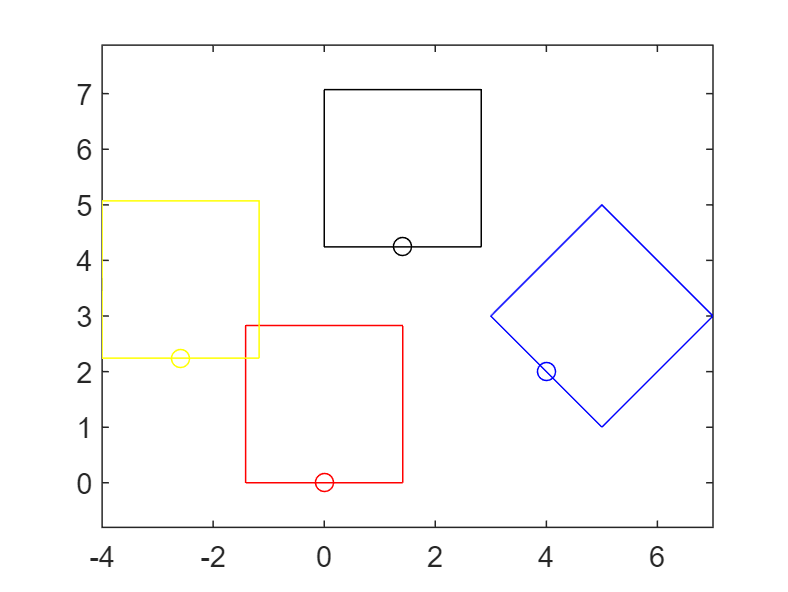

scatter(p3Cx,p3Cy,'k');
axis equal;


ang = acosd((p0Cx*p3Cx + p0Cy*p3Cy)/sqrt(p0Cx^2+p0Cy^2)/sqrt(p3Cx^2+p3Cy^2))

ang = 45